# **Pulso Retangular**

Um pulso retangular isolado de amplitude *A* e duração *T* pode ser representado matematicamente como: 


$$g\left(t\right)=A\cdot rect\left(\frac{t}{T}\right)$$


Definimos primeiramente a taxa de amostragem e a amplitude do pulso. 

fs =500; % taxa de amostragem 
V = 1; % V, amplitude do pulso retangular

Em seguida definimos a largura e a base de tempo para representação.

T = 0.2; % s, largura do pulso retangular
t = -0.5:1/fs:0.5; % base de tempo

Definimos então o sinal.

g = V*((t>-T/2).*(t<T/2)+0.5*(t==T/2)+0.5*(t==-T/2)); % equação do sinal

Plotando o resultado.

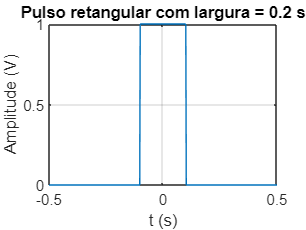

plot(t,g); % plota o sinal
grid on; % mostra linhas de grade
title(['Pulso retangular com largura = ', num2str(T), ' s']); % adiciona título
xlabel('t (s)'); % adiciona título no eixo x
ylabel('Amplitude (V)'); % adiciona título no eixo y